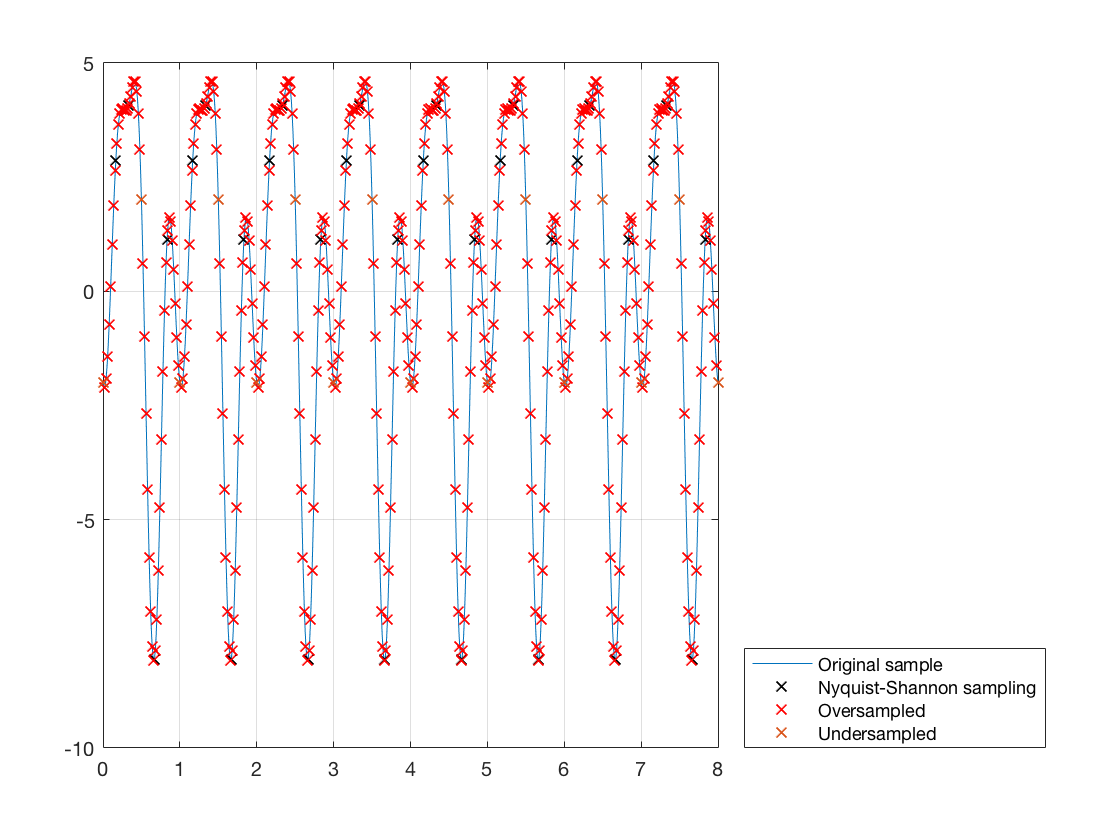

close all, clear all 
%Nyquist - Shannon sampling frequency: 6Hz >= 3Hz
dt1 = 1/100;
dt2 = 1/6; %Nyquist sampling rate
dt3 = 1/50; %Higher sampling than Nyquist
dt4 = 1/2; %Less sampling than Nyquist

st = 0;
et = 8;
t1 = st:dt1:et;
t2 = st:dt2:et;
t3 = st:dt3:et;
t4 = st:dt4:et;

y1 = 4*sin(2*pi*t1)-2*cos(6*pi*t1)-3*sin(4*pi*t1);
y2 = 4*sin(2*pi*t2)-2*cos(6*pi*t2)-3*sin(4*pi*t2);
y3 = 4*sin(2*pi*t3)-2*cos(6*pi*t3)-3*sin(4*pi*t3);
y4 = 4*sin(2*pi*t4)-2*cos(6*pi*t4)-3*sin(4*pi*t4);
plot(t1,y1), hold on
plot(t2,y2,'kx'), grid on 
plot(t3,y3,'rx')
plot(t4,y4,'x'), hold off
legend('Original sample','Nyquist-Shannon sampling',...

    'Oversampled','Undersampled','location','southeastoutside')
